# **第一章 MATLAB编程基础**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## **1.1 变量命名规则**

        在MATLAB中，变量名是区分大小写的，譬如：运行下方的两行代码后，将在Workspace中同时看到变量A和a。

A = 2

A = 2

a = 3

a = 3

        在64位计算机中，MATLAB规定变量名的长度不超过63位，譬如：下方的代码中我们定义一个变量名长度为64位的变量，运行后MATLAB不会报错，但会给出一个警告（提示超出最大限制），同时会对变量名进行自动截断，超出63位的部分将被删除。

ABCDEFGHIJKLMNOPQRSTUVWXYZ123456ABCDEFGHIJKLMNOPQRSTUVWXYZ123456 = 3        

ABCDEFGHIJKLMNOPQRSTUVWXYZ123456ABCDEFGHIJKLMNOPQRSTUVWXYZ12345 = 3

        MATLAB中规定：变量名以字母开头，可以由字母、数字和下划线组成，但不能使用标点。譬如：下方被注释的四行代码中的变量名均违反了MATLAB变量命名规则，运行后将会报错。

% 3A = 4
% .a = 5
% /b = 5
% a.2 = 4

        为了更容易理解代码，在给变量进行命名时应遵循“简洁、明了”的原则，即通过变量名可以直观看出变量所表示的物理意义。一般情况下，可以采用驼峰命名法对变量进行命名，如下方代码所写：

convolutionKernel = rand(3, 3)      % 小驼峰命名法

convolutionKernel =     0.1788    0.5985    0.6999
    0.4229    0.4709    0.6385
    0.0942    0.6959    0.0336


convolutionKernel = rand(5, 5)      % 大驼峰命名法

convolutionKernel =     0.0688    0.8200    0.1056    0.2665    0.4574
    0.3196    0.7184    0.6110    0.1537    0.8754
    0.5309    0.9686    0.7788    0.2810    0.5181
    0.6544    0.5313    0.4235    0.4401    0.9436
    0.4076    0.3251    0.0908    0.5271    0.6377


## **1.2 常用数据类型**

        MATLAB中常用的数据类型包括：常数、字符与字符串、矩阵、元胞数组和结构体等，各种类型数据的具体用法如下：

% 常数类型的四则运算
A = 2 + 4

A = 6

B = 10 - 7

B = 3

C = 3 * 5

C = 15

D = 8 / 2

D = 4


% 字符与字符串
s = 'a'

s = 'a'

abs(s)          % 返回字符'a'的ASCII值

ans = 97

char(65)        % 将ASCII值65转换为相应的字符

ans = 'A'

num2str(65)     % 将数值65转换为字符串'65'

ans = '65'


% 矩阵
A = [1 2 3; 4 5 2; 3 2 7];      % 同一行的元素之间，用空格或逗号隔开；分号表示一行元素的结束。
B = A'                          % 矩阵A的转置

B =      1     4     3
     2     5     2
     3     2     7


C = A(:)                        % 将矩阵A转换为一个列向量（按照列的顺序，即依次为：第一列、第二列、...）

C =      1
     4
     3
     2
     5
     2
     3
     2
     7


D = inv(A)                      % 矩阵A的逆矩阵（A的逆矩阵存在）

D =    -0.9118    0.2353    0.3235
    0.6471    0.0588   -0.2941
    0.2059   -0.1176    0.0882


E = pinv(A)                     % 矩阵A的伪逆矩阵（A的逆矩阵不存在）

E =    -0.9118    0.2353    0.3235
    0.6471    0.0588   -0.2941
    0.2059   -0.1176    0.0882


A * D

ans =     1.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000
    0.0000    0.0000    1.0000



E = zeros(10,5,3)               % 创建一个10*5*3的三维矩阵，元素全部为0

E = E(:,:,1) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


E(:,:,2) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


E(:,:,3) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


E(:,:,1) = rand(10,5)         

E = E(:,:,1) =

    0.9577    0.8444    0.4243    0.1527    0.2875
    0.2407    0.3445    0.4609    0.3411    0.0911
    0.6761    0.7805    0.7702    0.6074    0.5762
    0.2891    0.6753    0.3225    0.1917    0.6834
    0.6718    0.0067    0.7847    0.7384    0.5466
    0.6951    0.6022    0.4714    0.2428    0.4257
    0.0680    0.3868    0.0358    0.9174    0.6444
    0.2548    0.9160    0.1759    0.2691    0.6476
    0.2240    0.0012    0.7218    0.7655    0.6790
    0.6678    0.4624    0.4735    0.1887    0.6358


E(:,:,2) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


E(:,:,3) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0

E(:,:,2) = randi(5, 10,5)

E = E(:,:,1) =

    0.9577    0.8444    0.4243    0.1527    0.2875
    0.2407    0.3445    0.4609    0.3411    0.0911
    0.6761    0.7805    0.7702    0.6074    0.5762
    0.2891    0.6753    0.3225    0.1917    0.6834
    0.6718    0.0067    0.7847    0.7384    0.5466
    0.6951    0.6022    0.4714    0.2428    0.4257
    0.0680    0.3868    0.0358    0.9174    0.6444
    0.2548    0.9160    0.1759    0.2691    0.6476
    0.2240    0.0012    0.7218    0.7655    0.6790
    0.6678    0.4624    0.4735    0.1887    0.6358


E(:,:,2) =

     5     2     2     4     4
     2     4     2     3     4
     4     3     1     5     4
     2     5     5     2     5
     1     5     4     1     5
     4     2     3     1     1
     3     4     4     1     1
     3     3     3     3     4
     4     3     4     3     1
     4     5     3     2     3


E(:,:,3) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0

E(:,:,3) = randn(10,5)

E = E(:,:,1) =

    0.9577    0.8444    0.4243    0.1527    0.2875
    0.2407    0.3445    0.4609    0.3411    0.0911
    0.6761    0.7805    0.7702    0.6074    0.5762
    0.2891    0.6753    0.3225    0.1917    0.6834
    0.6718    0.0067    0.7847    0.7384    0.5466
    0.6951    0.6022    0.4714    0.2428    0.4257
    0.0680    0.3868    0.0358    0.9174    0.6444
    0.2548    0.9160    0.1759    0.2691    0.6476
    0.2240    0.0012    0.7218    0.7655    0.6790
    0.6678    0.4624    0.4735    0.1887    0.6358


E(:,:,2) =

     5     2     2     4     4
     2     4     2     3     4
     4     3     1     5     4
     2     5     5     2     5
     1     5     4     1     5
     4     2     3     1     1
     3     4     4     1     1
     3     3     3     3     4
     4     3     4     3     1
     4     5     3     2     3


E(:,:,3) =

    0.0355   -1.3429    0.6293   -0.5316    0.6489
    2.2272   -1.0322   -0.2130    0.9726   -0.3601
   -0.0692    1.3312   -0.8657   -


% 元胞数组
A = cell(1, 6)      % 创建一个1*6的元胞数组A

A = 1×6 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


A{2} = eye(3)       % 将一个3阶单位阵赋值给元胞数组A的第二个位置

A = 1×6 cell array
    {0×0 double}    {3×3 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


A{5} = magic(5)     % 将一个5阶魔方阵赋值给元胞数组A的第五个位置

A = 1×6 cell array
    {0×0 double}    {3×3 double}    {0×0 double}    {0×0 double}    {5×5 double}    {0×0 double}


B = A{5}            % 查看元胞数组A第五个位置的元素（类型为二维数组）

B =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


C = A(5)            % 取出元胞数组A第五个位置的元素（类型仍为元胞数组）

C = 1×1 cell array
    {5×5 double}



% 结构体
books = struct('name',{{'Machine Learning','Data Mining'}},'price',[30 40])

books = struct with fields:
     name: {'Machine Learning'  'Data Mining'}
    price: [30 40]


books.name

ans = 1×2 cell array
    {'Machine Learning'}    {'Data Mining'}


books.name(1)

ans = 1×1 cell array
    {'Machine Learning'}


A =      1     2     3     5     8     5     4     6


B =      1     3     5     7     9


C =      1     3     5     7     9     1     3     5     7     9
     1     3     5     7     9     1     3     5     7     9
     1     3     5     7     9     1     3     5     7     9


D =      1     1     1     1
     1     1     1     1


       ** 注意：**

- **与C语言不同，MATLAB在定义变量之前不需要声明类型，会根据给变量的赋值自动决定变量的类型；**

- **变量的类型在Workspace中可以查看到，也可以使用函数class()返回；**

- **MATLAB中，若一行代码的最后有“;”，则表示运行该行代码后，变量结果不会在Command Window中打印出来；**

- **元胞数组可以看作是一个容器，可以将不同类型的元素存放到同一个变量中；在对元胞数组进行操作时，需要格外关注{}和()的区别；**

- **后面章节中很多模型都是封装成结构体类型的，需要学会结构体的基本操作方法，学会从结构体中取出感兴趣的内容。**

## **1.3 矩阵操作**

        熟练掌握矩阵操作是掌握好MATLAB的关键，矩阵操作通常包括如下三个方面：

- **矩阵的定义与构造。**除了要学会通过给矩阵赋值的方法创建矩阵外，还要熟练掌握MATLAB自带的矩阵构造函数，可以帮助我们快速创建出一些特定结构的矩阵，**譬如：zeros()、ones()、eye()、rand()、randi、randn()**等，具体的用法可以参考对应的帮助文档。帮助文档页面中有一个板块“See Also”，可以辅助我们从一个函数联想记忆更多的相关函数。

- **矩阵的四则运算：**矩阵的加法和减法较为简单，操作数为相同维度的两个矩阵，和/差为一个相同维度的矩阵；矩阵的点乘（.*）和点除（./）与加减法类似；矩阵的乘法和除法遵循线性代数中的定义，A*B需要满足矩阵A的列数与矩阵B的行数相等；矩阵除法则对应计算矩阵的逆矩阵。

- **矩阵的索引与切片：**与C、Python等语言不同，MATLAB中矩阵的索引是从1开始的。需要熟练掌握如下操作：（1）根据给定的行索引与列索引，从矩阵中取出相应位置的元素；（2）根据给定的行索引与列索引，从矩阵中取出相应的某一行/列，或某几行/列；（3）从矩阵中查询满足某个特定条件的元素，返回符合查询条件的元素所对应的行索引与列索引。

% 矩阵的定义与构造
A = [1 2 3 5 8 5 4 6]

A =      1     2     3     4
     5     6     7     8


B = 1:2:9                   % B = [1 3 5 7 9]

B =      1     1     2     2
     2     2     1     1


C = repmat(B, 3, 2)         % 将行向量B沿着行的方向复制3份，沿着列的方向复制2份，最终得到的矩阵C的维度为3*10

C =      2     3     5     6
     7     8     8     9


D = ones(2, 4)

D =      0     1     1     2
     3     4     6     7


E =     17    13
    41    37


% 矩阵的四则运算

F =      1     2     6     8
    10    12     7     8


A = [1 2 3 4; 5 6 7 8]

G =     1.8333   -0.1667
    3.1667    1.1667


B = [1 1 2 2; 2 2 1 1]

H =     1.0000    2.0000    1.5000    2.0000
    2.5000    3.0000    7.0000    8.0000


C = A + B
D = A - B
E = A * B'

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


F = A .* B

B = 7

G = A / B                   % G * B = A     G * B * pinv(B) = A * pinv(B)    G = A * pinv(B)

C =      4     6    13    20    22


H = A ./ B

D =      8
    14
    20
    21
     2


m =      2
     1
     5
     4
     3


n =      1
     2
     3
     4
     5


% 3. 矩阵的下标
A = magic(5)
B = A(2,3)                  % 从矩阵A中取出第2行、第3列的元素
C = A(3,:)                  % 从矩阵A中取出第3行的所有元素
D = A(:,4)                  % 从矩阵A中取出第4列的所有元素
[m, n] = find(A > 20)       % 从矩阵A中查询满足条件A>20的所有元素，并返回其对应的行索引与列索引

A =     0.1548    0.1999    0.4070    0.7487    0.8256    0.7900    0.3185    0.5341    0.0900    0.1117


Indices of values > 0.752346: 


     5     6



## **1.4 逻辑与流程控制**

        逻辑与流程控制是所有编程语言的重要组成部分，使得程序不必严格按照顺序从上向下运行，而可以跳转到某行执行，或重复执行某个代码片段多次。MATLAB中逻辑与流程控制一共包含如下四种类型：

- **条件判断：**当条件满足时，执行相应的代码块；当条件不满足时，继续判断下一个条件；

- **for循环：**循环变量从初始值开始，依照步长不断增加，一直到循环变量大于等于终止值，停止运行；**注意：for循环适用循环变量的初始值、步长和终止值均是已知的场景。**

- **while循环：**适用的场景是不清楚循环究竟要执行多少次，但知道当满足某个条件时循环应停下来。一般情况下，while关键字后跟的条件在初始化时应是满足的，否则while循环进不来；循环体内应有改变循环变量的代码，方能使得条件从满足变为不满足，循环才能停下来，否则while循环将会一直执行，即出现“死循环”的情况。

- **switch case：**适用的场景是变量的值为可以枚举出的若干个值，当变量的值等于某个值时，则执行相应的代码片段。

        四种不同的逻辑与流程控制具体的示例代码如下：

% 条件判断
A = rand(1,10)
limit = 0.752345678;

B = (A > limit);   % B是一个logical类型的一维数组，当A>limit时，返回值为逻辑"1"，否则为逻辑"0"。
if any(B)
    fprintf('Indices of values > %4.6f: \n', limit);
    disp(find(B))
else
    disp('All values are below the limit.')
end

m = 1

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

m = 3

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

m = 5

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

m = 7

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

m = 9

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10


% for循环
k = 10;
hilbert = zeros(k,k);   

hilbert =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
         0         0         0         0         0         0         0         0         0         0
    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
         0         0         0         0         0         0         0         0         0         0
    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
         0         0         0         0         0         0         0         0         0         0
    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
         0         0         0         0         0         0         0         0         0         0
    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
         0         0         0         0         0         0         0         0 


for m = 1:2:k
    m
    for n = 1:k
        n
        hilbert(m,n) = 1/(m+n -1);
    end
end
hilbert

n = 70


% while循环

ans = 1.7112e+98

n = 1;

ans = 1.1979e+100

nFactorial = 1;
while nFactorial < 1e100            % 寻找究竟时那个数的阶乘＞1e100，而其前一个数的阶乘小于1e100。
    n = n + 1;
    nFactorial = nFactorial * n;
end
n

factorial(69)
factorial(70)

% switch ... case ... end
mynumber = input('Enter a number:');
% 

other value


switch mynumber
    case -1
        disp('negative one');
    case 0
        disp('zero');
    case 1
        disp('positive one');
    otherwise
        disp('other value');
end

C = 8

D = -2

E = 15

F = 0.6000

## **1.5 函数定义与调用**

        尽管MATLAB中内置了丰富的函数供我们调用，但在许多情况下仍需要我们自定义一些函数，以使得代码更为简洁，以及代码的管理更清晰。函数的创建需要单独新建一个文件（譬如：当前工作路径下的FourOperation.m），文件内以function关键字开头，以end关键字结束。确保函数名与文件名一致，否则会产生歧义，同时函数名要避免与MATLAB内置的函数相同。

        **注意：当我们从别的渠道拿到一个代码文件夹，打开后看到其中有多个*.m格式的文件，一般情况下都有一个文件为主程序，其它的文件均为函数文件，需要找到主程序文件并运行，而函数文件是不能够直接运行的。**

        当函数定义好后，就可以在脚本文件中调用该函数，传进去实参就可以得到返回的结果了，如下方代码所写：

A = 3;
B = 5;
[C,D,E,F] = FourOperation(A,B)

## **1.6 基本图形绘制**

       如图1所示，一个标准的科研绘图应包括的元素包括：标题（Title）、横坐标名称（X axis label）、纵坐标名称（Y axis label）、线（Line）、散点（Markers）、图例（Legend）、网格（Grid）、刻度（Major tick、Minor tick）、刻度名称（Major tick label、Minor tick label）等。

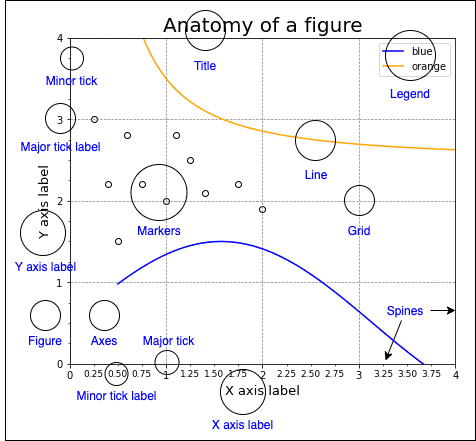

图1 科研绘图的基本要素

        MATLAB内置了丰富的图形绘制函数，基本的用法如下：

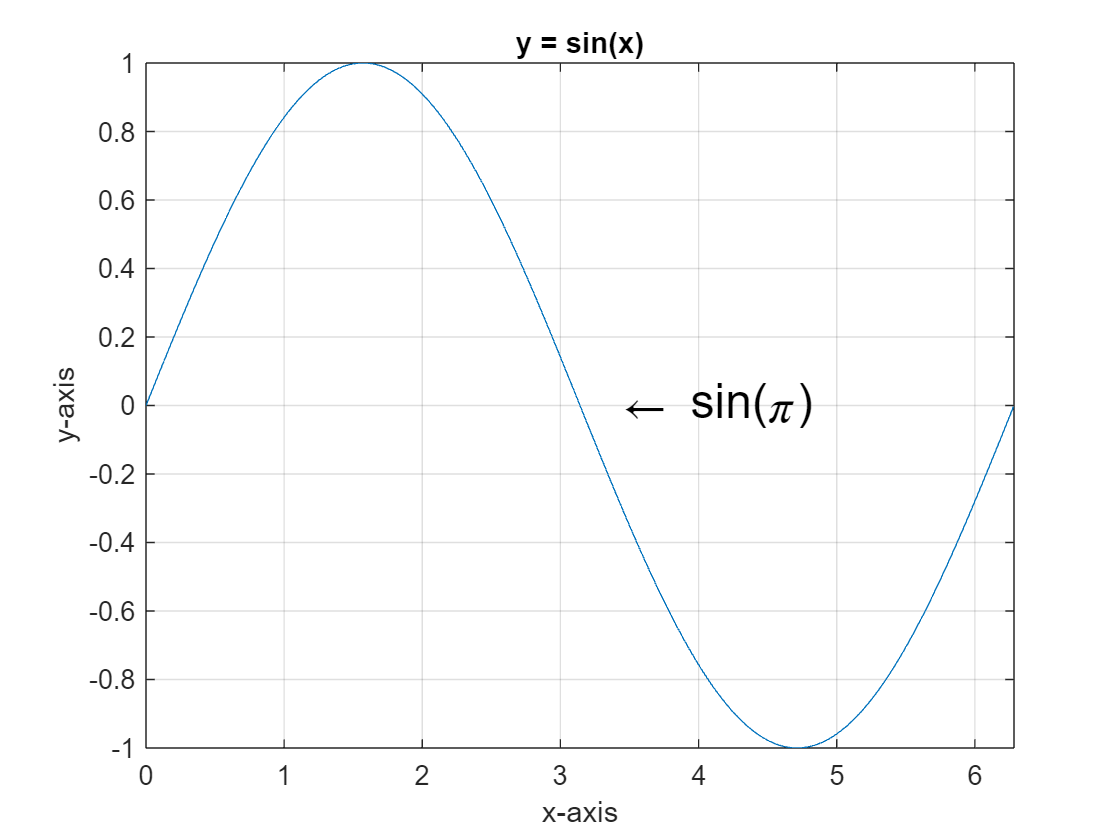

% plot/xlabel/ylabel/title/xlim/grid/text

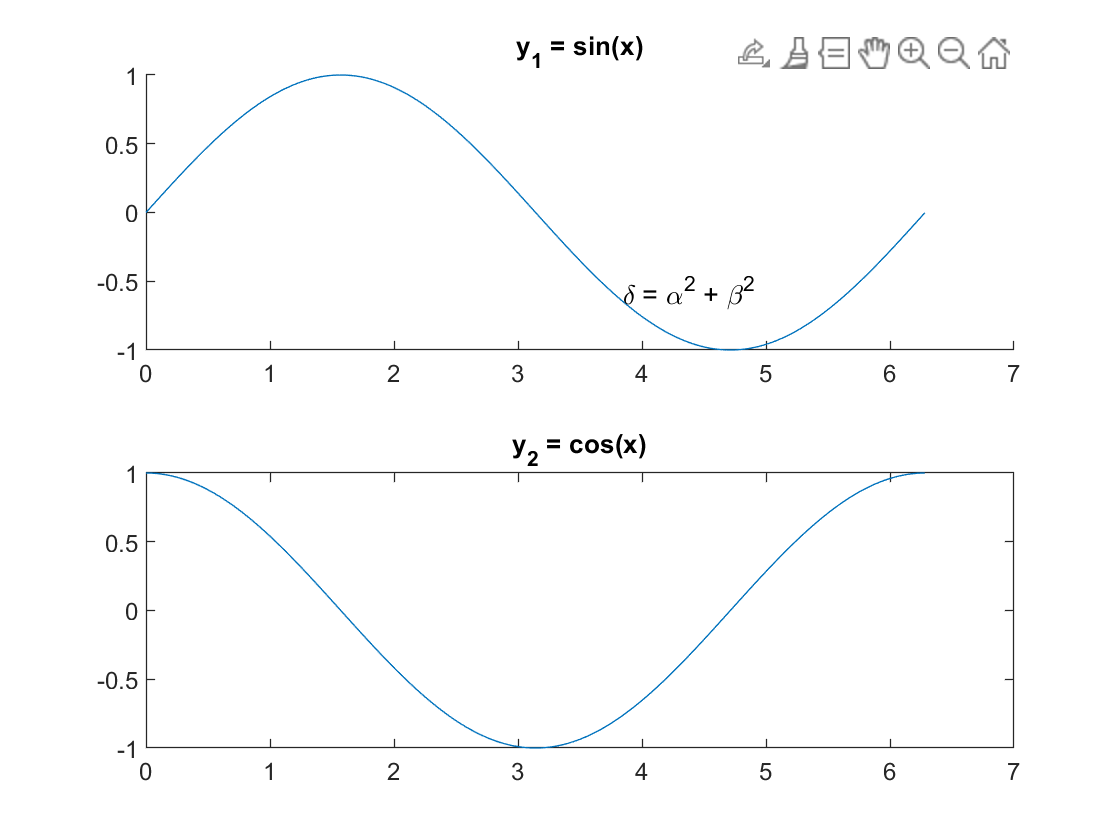

x = 0:0.01:2*pi;
y = sin(x);
plot(x,y)
xlabel('x-axis')
ylabel('y-axis')
title('y = sin(x)')
xlim([0 2*pi])
grid on
text(pi,0,' \leftarrow sin(\pi)','FontSize',18)

% subplot/box/gtext/Tex
figure
x = 0:0.01:2*pi;
y1 = sin(x);

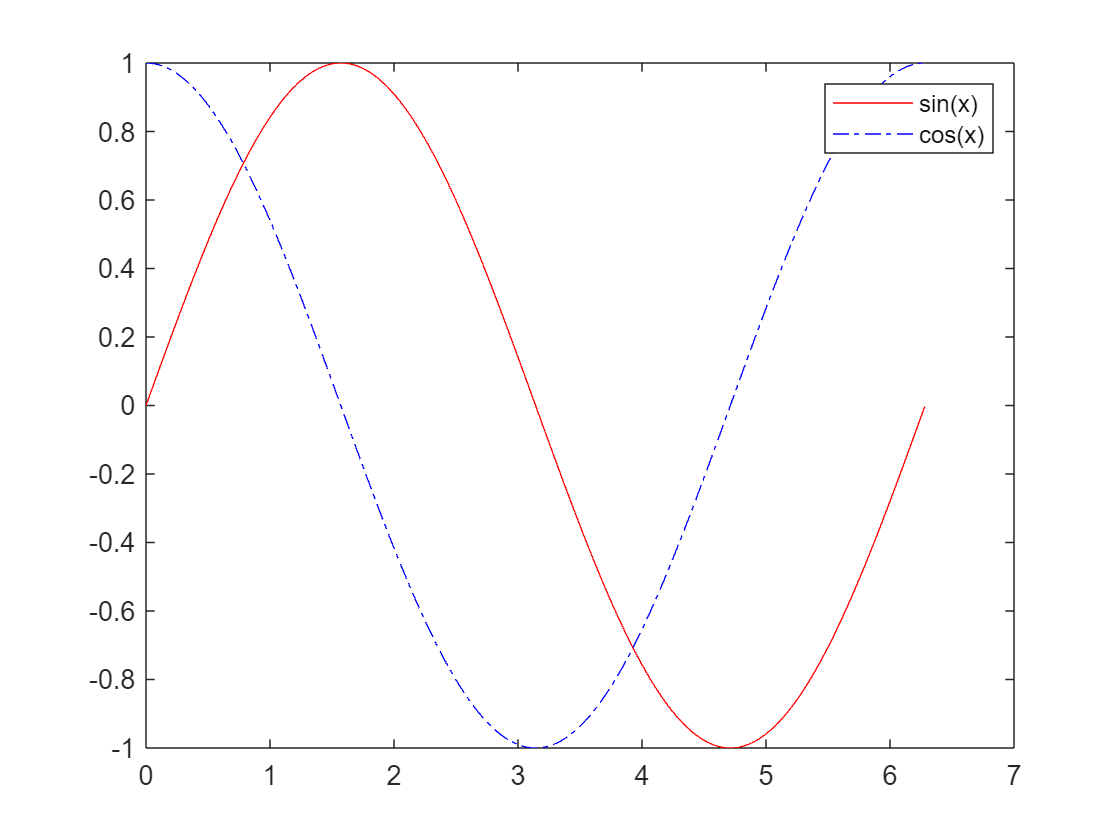

y2 = cos(x);
subplot(2,1,1)
plot(x,y1)
box off
title('y_1 = sin(x)')
subplot(2,1,2)
plot(x,y2)
title('y_2 = cos(x)')
gtext('\delta = \alpha^2 + \beta^2')


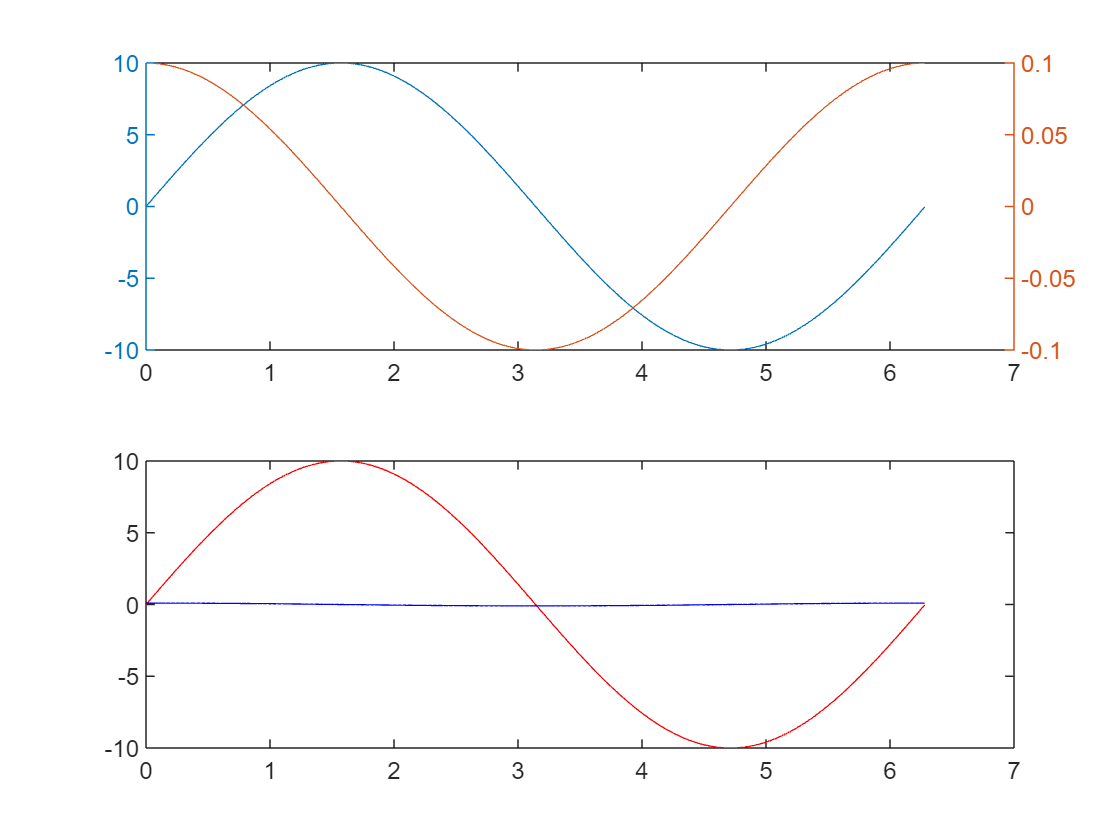

% legend/hold
figure
x = 0:0.01:2*pi;
y1 = sin(x);
y2 = cos(x);
plot(x,y1,'r')
hold on
plot(x,y2,'-.b')
legend('sin(x)','cos(x)')

% yyaxis left/right
figure
x = 0:0.01:2*pi;
y1 = sin(x) * 10;
y2 = cos(x) / 10;
subplot(2,1,1)

yyaxis left
plot(x, y1)
yyaxis right
plot(x, y2)

subplot(2,1,2)
plot(x,y1,'r')
hold on

      AffectAutoLimits: on
    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
                 Color: [0 0.4470 0.7410]
             ColorMode: 'auto'
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: ''
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
              LineJoin: 'round'
             LineStyle: '-'
         LineStyleMode: 'auto'
             LineWidth: 0.5000
                Marker: 'none'
       MarkerEdgeColor: 'auto'
       MarkerFaceColor: 'none'
         MarkerIndices: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 

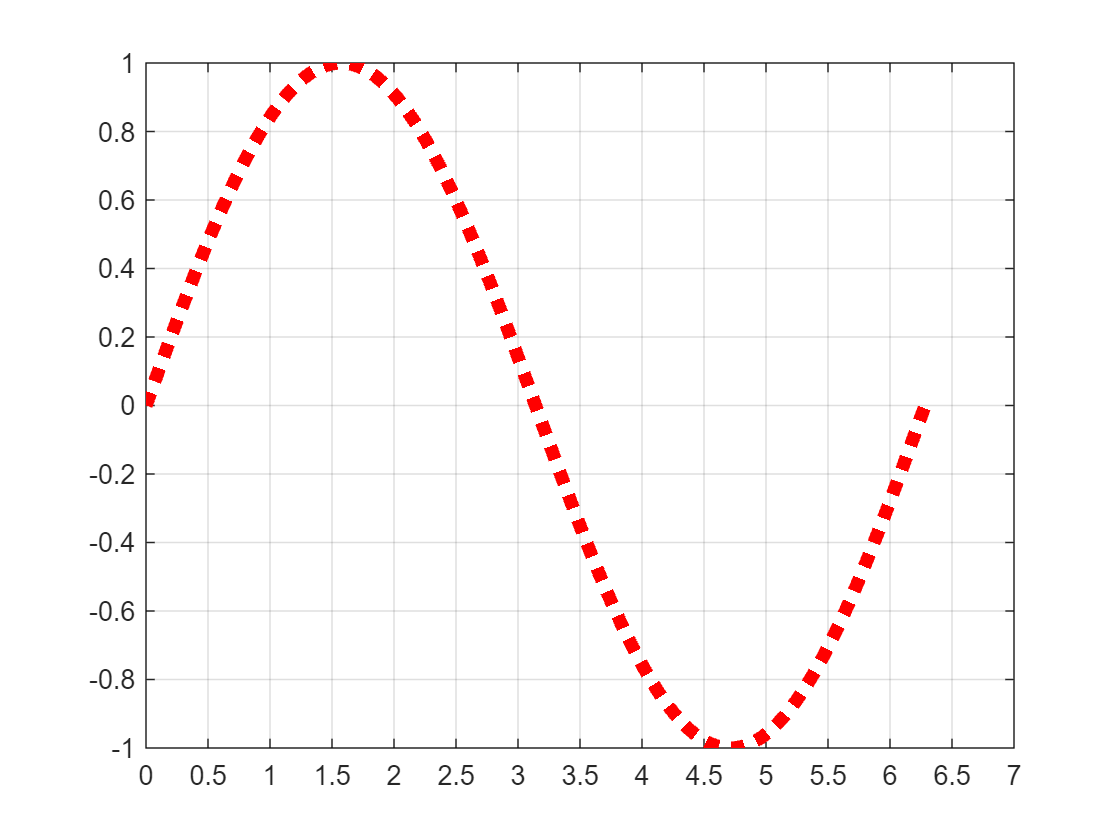

plot(x,y2,'b')

% 如何设置线条的属性呢？
figure

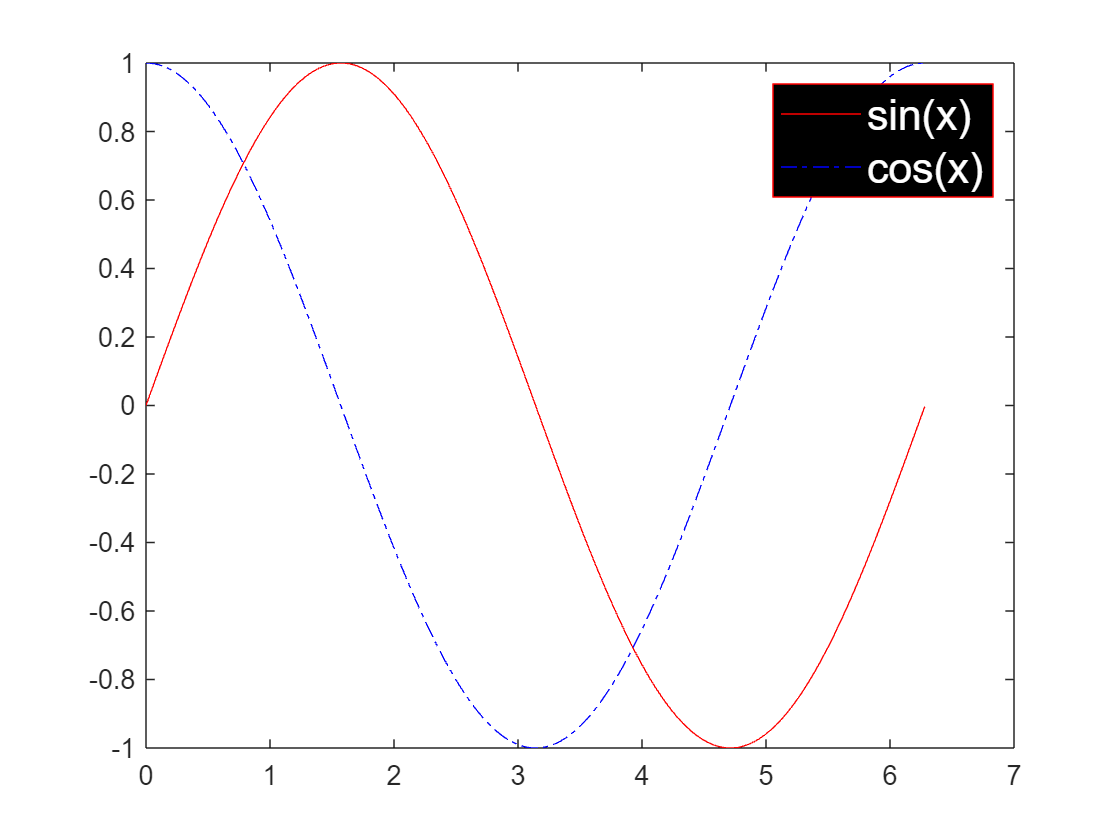

x = 0:0.01:2*pi;
y = sin(x);
h = plot(x,y);
grid on
get(h)
set(h,'linestyle',':','linewidth',5,'color','r')

% 如何修改网格的间隔呢？
set(gca,'xtick',0:0.5:7)
% get current axes

% 如何设置图例的字体及大小呢？

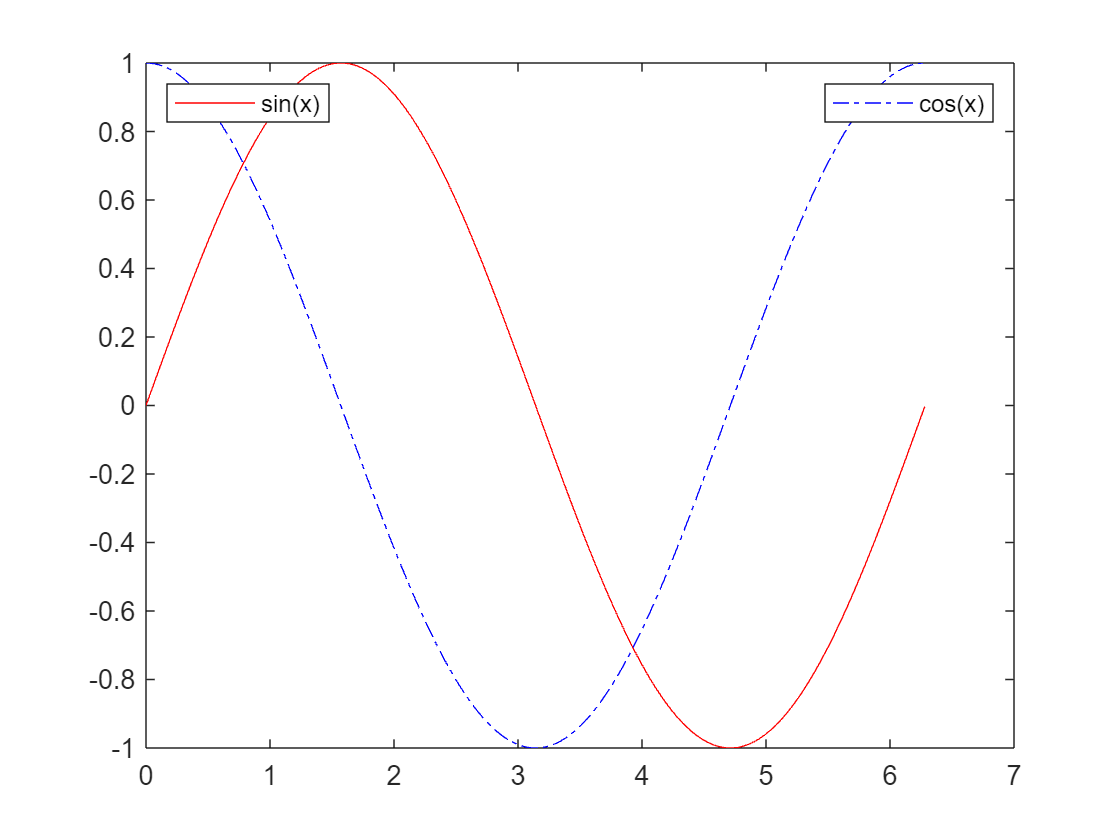

figure
x = 0:0.01:2*pi;
y1 = sin(x);
y2 = cos(x);
plot(x,y1,'r')
hold on
plot(x,y2,'-.b')
h = legend('sin(x)','cos(x)');
set(h,'fontsize',16,'color','k','edgecolor','r','textcolor','w')

% 如何拆分图例呢？
figure
x = 0:0.01:2*pi;

y1 = sin(x);
y2 = cos(x);
h1 = plot(x,y1,'r');
hold on
h2 = plot(x,y2,'-.b');
ax1 = axes('position',get(gca,'position'),'visible','off');
legend(ax1,h1,'sin(x)','location','northwest')
ax2 = axes('position',get(gca,'position'),'visible','off');
legend(ax2,h2,'cos(x)','location','northeast')

## **1.7 常见格式文件读写**

        常见的数据格式包括：*.mat、*.txt、*.xls/xlsx、*.csv、*.wav等，对应的读写示例代码如下：

% mat格式
x = 0:0.1:2*pi;
y1 = sin(x);
y2 = cos(x);
save data.mat
clear all
load data.mat

ans = logical
   1



% txt格式
M = importdata('myfile.txt');

S = M.data;

ans = logical
   1


save 'data.txt' S -ascii
T = load('data.txt');

isequal(S, T)     % 判断变量S和变量T是否相等

ans = logical
   1



% xls格式
writematrix(S, 'data.xls')
W = readmatrix('data.xls');
isequal(S, W)

ans = logical
   1



writematrix(S, 'data.xlsx')
U = readmatrix('data.xlsx');
isequal(S, U)

% csv格式
writematrix(S, 'data.csv')
V = readmatrix('data.csv');
isequal(S, V)

% 音频格式
load handel.mat
 
hfile = 'handel.wav';
audiowrite(hfile, y, Fs)
clear y Fs
 
[y, Fs] = audioread(hfile);
sound(y, Fs);

## **1.8 程序调式方法**

        在程序开发的过程中，每一个人都会遇到代码调试的问题。为什么有的人能够很快找到错误发生的原因，而有的人花很长时间却仍然是一头雾水？根据笔者多年的编程经验，给出下面的几条体会与建议：

- **首先，需要克服心理上的恐惧和障碍。**“闻道有先后，术业有专攻”，所谓的“高手”只是遇到错误更早一点、遇到的次数更多一些而已。对于遇到的错误，要有充足的信心，一定可以成功调试出来。

- **其次，要认真研读错误信息。**错误信息中蕴含了重要的信息（包括：错误发生的代码行、错误发生的原因等），因此需要认真研读错误信息的内容（建议至少三遍以上）。若仍然无法从错误信息中得出解决方法，可以尝试将错误信息输入到搜索引擎或ChatGPT，查询相应的解决方案。

- **第三，利用断点调试工具进行调试。**在有效代码行（左侧可以看到用数字表示的行号），点击行号，即可设置断点（再次点击，即可取消断点），然后再逐行运行代码，边运行边观察Workspace中相关变量的取值，分析究竟是什么原因导致了错误的发生？

**        需要注意的是：若MATLAB软件的语言为中文（菜单均为中文），那么弹出的错误信息也是中文的，不利于搜索引擎检索。因此，建议将MATLAB软件的语言设置为英文。**

        下面的示例代码展示了经常可能遇到的8个错误，读者可以先取消注释下面的代码，运行并分析错误发生的原因。当逐渐熟练以后，**笔者可以尝试逆向思维，即根据错误信息写错误的代码片段，若能写得出来，表明笔者真正掌握了错误发生的本质。**

        另外，**建议笔者在运行每一行代码前，先思考、分析这一行代码运行后的结果是怎样的（值是多少？矩阵维度是多少？等等）， 然后再运行代码，对比Workspace中的变量结果与自己分析的结果是否一致？**                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          

% 1. Index must be a positive integer or logical.
% A = [1 2 3 4 5];
% A(0)
% A(3.5)
% A(-2)
% 
% 2. Undefined function or variable 'B'.
% B
% 
% 3. Inner matrix dimensions must agree.
% B = [1 2 3];
% A * B
% 
% 4. Function definitions are not permitted at the prompt or in scripts.
% function c = add(a,b)
% c = a + b;
% 
% 5. Index out of bounds because numel(A)=5.
% A(6)
% 
% 6. In an assignment  A(I) = B, the number of elements in B and I must be the same.
% A(3) = B;
% 
% 7. Expression or statement is incorrect--possibly unbalanced (, {, or [.
% mean(A(1:3)
% 
% 8. Too many input arguments.
% mean(A,1,2)